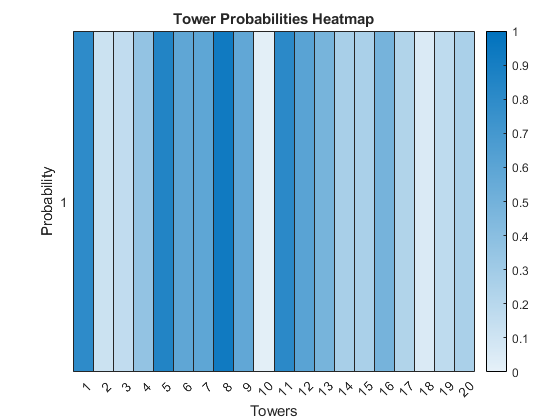

% Define the parameters
clc; clear;
numAnts = 4;
numIterations = 10;
alpha = 1.0;   % Pheromone importance
beta = 3;    % Prob importance
evaporationRate = 0.05;

% Generate random tower positions and probabilities
numTowers = 20;
towerProbabilities = rand(numTowers, 1);

% Reshape the array for heatmap
heatmapData = reshape(towerProbabilities, 1, []);

% Plot the heatmap
figure;
heatmap(heatmapData, 'ColorLimits', [0, 1], ...
    'XLabel', 'Towers', 'YLabel', 'Probability', 'Title', 'Tower Probabilities Heatmap');

Iteration 1: Min Average Probability = 0.4037


Iteration 2: Min Average Probability = 0.4037
Iteration 3: Min Average Probability = 0.3532
Iteration 4: Min Average Probability = 0.3404
Iteration 5: Min Average Probability = 0.3404
Iteration 6: Min Average Probability = 0.3404
Iteration 7: Min Average Probability = 0.3404
Iteration 8: Min Average Probability = 0.3404
Iteration 9: Min Average Probability = 0.3404
Iteration 10: Min Average Probability = 0.3404


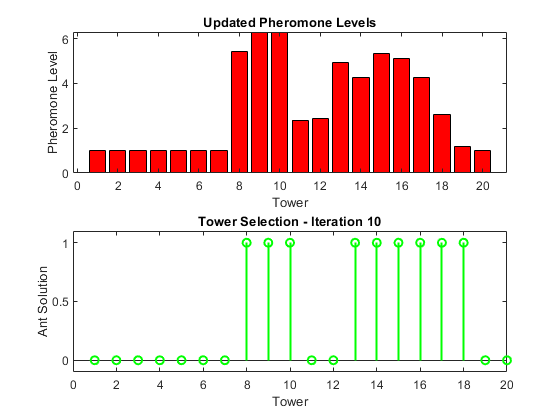


% Define problem-specific parameters
k = 10;    % Number of TLAs to install
minConsecutiveTLAs = 3;

% Initialize pheromone levels
pheromoneLevels = ones(numTowers, 1);

% Initialize the best solution and its probability
bestSolution = [];
minAvgProbability = 1;

for iteration = 1:numIterations
    antSolutions = cell(numAnts, 1); % Empty array
    antProbabilities = zeros(numAnts, 1);

    for ant = 1:numAnts
        visited = false(numTowers, 1); % Logical zeros
        antSolution = zeros(k, 1); % TLAs install index, black = 1, white = 0

        % Construct the solution
        for tower = 1:numTowers
            % Calculate probabilities for unvisited towers using pheromones
            unvisitedIndices = find(~visited);
            probabilities = (pheromoneLevels(unvisitedIndices) .^ alpha) .* (towerProbabilities(unvisitedIndices) .^ beta);
            probabilities = probabilities / sum(probabilities);

            % Choose tower with pheromone-based probability
            chosenTower = chooseWithProbability(probabilities, pheromoneLevels, alpha, beta);

            if ~isempty(chosenTower)
                % Update the antSolution and visited array
                antSolution = installTLAs(chosenTower, antSolution, k, minConsecutiveTLAs);
                visited(chosenTower) = true;
            end
        end

        antSolutions{ant} = antSolution;
        antProbabilities(ant) = mean(towerProbabilities(antSolution(antSolution <= numTowers)));
    end

    % Update pheromone levels based on the best ant solution
    [~, bestAnt] = min(antProbabilities);
    bestAntSolution = antSolutions{bestAnt};
    
    for i = 1:k - minConsecutiveTLAs + 1
        rangeEnd = min(i + minConsecutiveTLAs - 1, numTowers);
        subSolution = bestAntSolution(i:rangeEnd);
        
        avgProbability = mean(towerProbabilities(subSolution));
        pheromoneLevels(subSolution) = (1 - evaporationRate) * pheromoneLevels(subSolution) + avgProbability;
    end


    

    % Update the best solution if a better one is found
    if antProbabilities(bestAnt) < minAvgProbability
        bestSolution = bestAntSolution;
        minAvgProbability = antProbabilities(bestAnt);
    end

    % Display the best solution in this iteration
    fprintf('Iteration %d: Min Average Probability = %.4f\n', iteration, minAvgProbability);

    % Plot the updated pheromone levels
    subplot(2, 1, 1);
    bar(1:numTowers, pheromoneLevels, 'r');
    title('Updated Pheromone Levels');
    xlabel('Tower');
    ylabel('Pheromone Level');

    % Pause for visualization (adjust as needed)
    pause(1);
    
    % Plot the tower selection for the best ant
    subplot(2, 1, 2);
    plotAntSolution(bestAntSolution, numTowers);
    title(['Tower Selection - Iteration ' num2str(iteration)]);
    xlabel('Tower');
    ylabel('Ant Solution');

    % Pause for visualization (adjust as needed)
    pause(1);
end


% Display the final best solution and its average probability
fprintf('Final Best Solution:\n');

Final Best Solution:


fprintf('Average Probability = %.4f\n', minAvgProbability);

Average Probability = 0.3404


fprintf('TLA Positions = %s\n', mat2str(bestSolution));

TLA Positions = [8;9;10;15;16;17;16;17;18;19]


function antSolution = installTLAs(tower, antSolution, k, minConsecutiveTLAs)
    not_installed = find(~antSolution);
    sumNonZero = sum(antSolution ~= 0);
    k_remain = k - sumNonZero;

    if k_remain >= 2 * minConsecutiveTLAs % install 3 TLAs
        for i = not_installed:minConsecutiveTLAs + not_installed - 1
            antSolution(i) = tower + i - 1;
        end
    else % install all TLAs left
        for i = not_installed:k_remain + not_installed - 1
            antSolution(i) = tower + i - 1;
        end
    end
end

function choice = chooseWithProbability(probabilities, pheromones, pheromoneImportance, beta)
    % Calculate probabilities for unvisited towers
    unvisitedIndices = find(probabilities > 0);
    probabilities = (pheromones(unvisitedIndices) .^ pheromoneImportance) .* (probabilities(unvisitedIndices) .^ beta);
    probabilities = probabilities / sum(probabilities);

    cumulativeProbabilities = cumsum(probabilities);
    if ~isempty(cumulativeProbabilities)
        randValue = rand() * cumulativeProbabilities(end);
        choice = unvisitedIndices(find(randValue <= cumulativeProbabilities, 1, 'first'));
    else
        % Handle the case when cumulativeProbabilities is empty
        choice = [];
    end
end


% Function to plot the tower selection for an ant solution
function plotAntSolution(antSolution, numTowers)
    antPlot = zeros(1, numTowers);
    antPlot(antSolution(antSolution ~= 0)) = 1;
    stem(1:numTowers, antPlot, 'g', 'LineWidth', 1.5);
    ylim([-0.1, 1.1]);
end
